# RSA (vol I). fMRI.  

**Author**: Javier Ortiz-Tudela (Goethe University)

**Email**: [ortiztudela@psych.uni-frankfurt.de](mailto:ortiztudela@psych.uni-frankfurt.de)

**Created on**: 10/05/2021

### Initialize some stuff.

Just run this section. Press Ctrl + Enter.

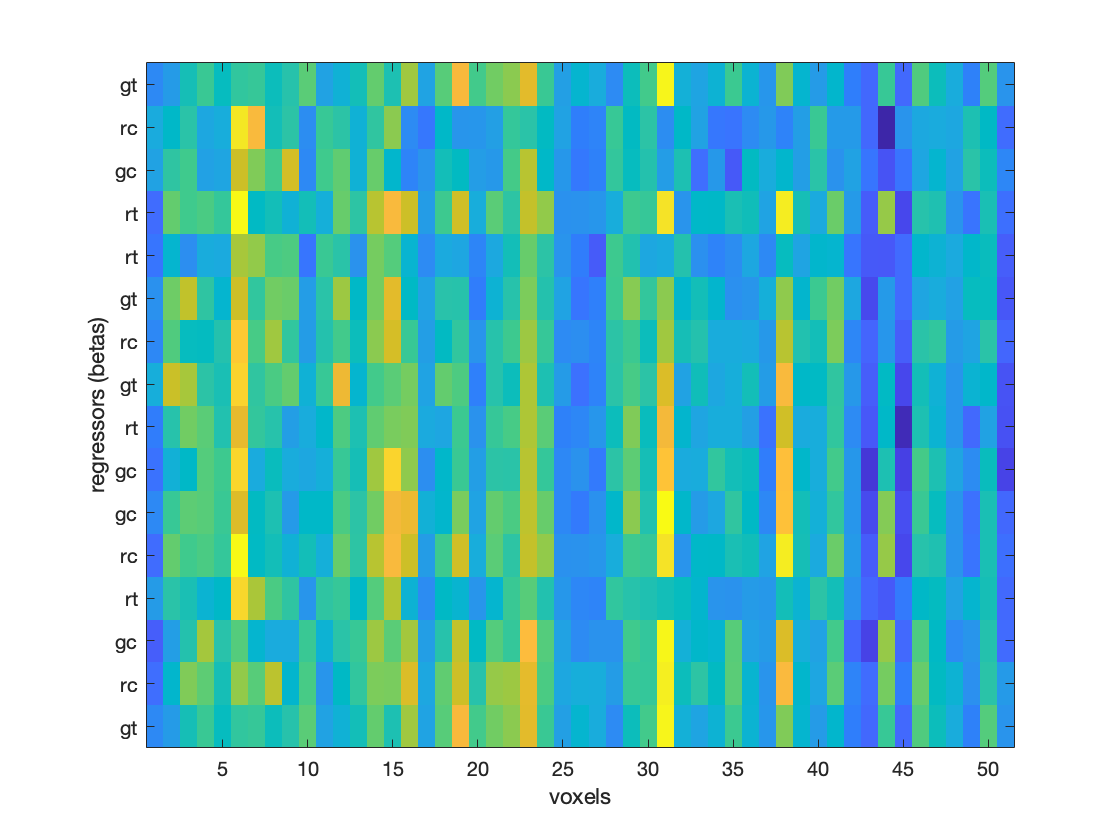

clear; close all
clc
load('beta_maps.mat')

% This is the bit that selects the voxels. Do not worry too much about
% understanding how the loop works: we are interested here on the outcome.
for cBeta=1:length(beta_maps)
    sel_voxels(cBeta,:)=beta_maps{cBeta}(v1_mask==1);
end
sel_voxels(isnan(sel_voxels))=0;


% Beta lables
beta_labels={'gt'; 'rc'; 'gc'; 'rt'; 'rt'; 'gt'; 'rc'; 'gt';...
    'rt'; 'gc'; 'gc'; 'rc'; 'rt'; 'gc'; 'rc'; 'gt'};

% Add pattern
sel_voxels(strcmpi(beta_labels, 'gt') | strcmpi(beta_labels, 'gc'),1:100:end) = 100;
sel_voxels(strcmpi(beta_labels, 'rt') | strcmpi(beta_labels, 'rc'),1:120:end) = 100;

% We can visualize our voxels as a matrix.
figure, imagesc(sel_voxels(:,150:200));
xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);

## Intoduction

By now you should already know what beta maps are. If you do not, go back to the slides and excersies from previous sessions.

We will use the same beta data as in the previous scripts. 

### Feature (i.e., voxels) selection.

We have also included a mask of V1. Remember that a mask is just a file for selecting a given brain region. This file is a volume in which the values of the voxels for the region that we want to select are set to 1 while keeping the rest at 0.

So far this is identical to what we have discussed for classifiers. Let's try to look at the same question as before. Can we find **shape information** in V1? 

To make visualizations nicer, we will sort betas by shape type.

% Turn old labels into 1s and 2s.
new_labels=zeros(16,1);
new_labels(strcmpi(beta_labels, 'gt'))=2;
new_labels(strcmpi(beta_labels, 'rt'))=2;
new_labels(strcmpi(beta_labels, 'gc'))=1;
new_labels(strcmpi(beta_labels, 'rc'))=1;

% Sort betas
[~, ind] = sort(new_labels);
sorted_betas = sel_voxels(ind,:);


No we are ready to compute pair-wise correlations between all pairs of observations.

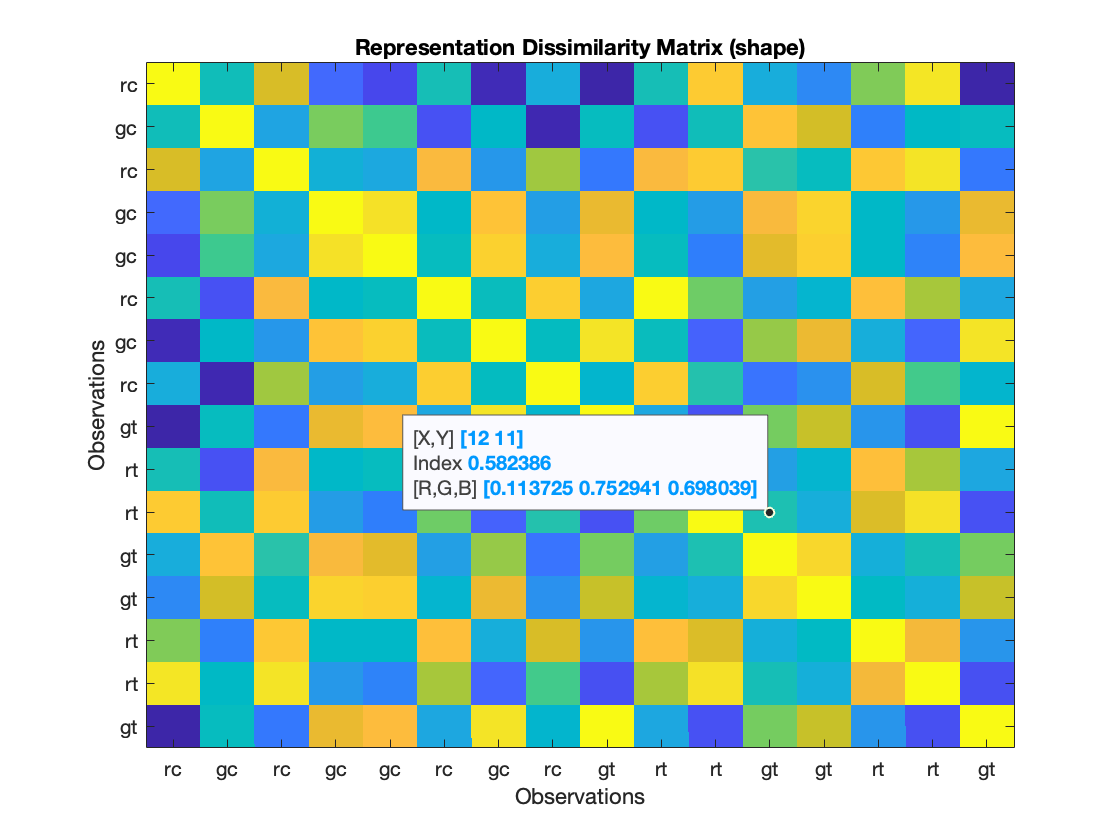

% How many observations do we have? Each beta is one observation.
n_observations = size(beta_maps,2);

% We will nest two loops to correlate each beta with every other beta
for outer_loop = 1:n_observations
    
    for inner_loop = 1:n_observations
        
        % Store correlation values in a big matrix (RDM)
        RDM_shape(outer_loop, inner_loop) = corr2(sorted_betas(outer_loop,:), sorted_betas(inner_loop,:));
        
    end
end

% Let's visualize our RDM
figure
imagesc(RDM_shape);xticks(1:16);yticks(1:16);xticklabels(beta_labels(ind));yticklabels(beta_labels(ind))
xlabel('Observations');ylabel('Observations');title('Representation Dissimilarity Matrix (shape)')

Do you understand this ouput? Do you see any evident patterns? Discuss it with group.

----

Same as before, we can also ask: is** color information **coded in our ROI? We need to re-code our labels and re-sort the betas to reflect the new question.

% Turn old labels into 1s and 2s.
new_labels=zeros(16,1);
new_labels(strcmpi(beta_labels, 'gt'))=2;
new_labels(strcmpi(beta_labels, 'rt'))=1;
new_labels(strcmpi(beta_labels, 'gc'))=2;
new_labels(strcmpi(beta_labels, 'rc'))=1;

% Sort betas
[~, ind] = sort(new_labels);
sorted_betas = sel_voxels(ind,:);

No we are ready to compute pair-wise correlations between all pairs of observations.

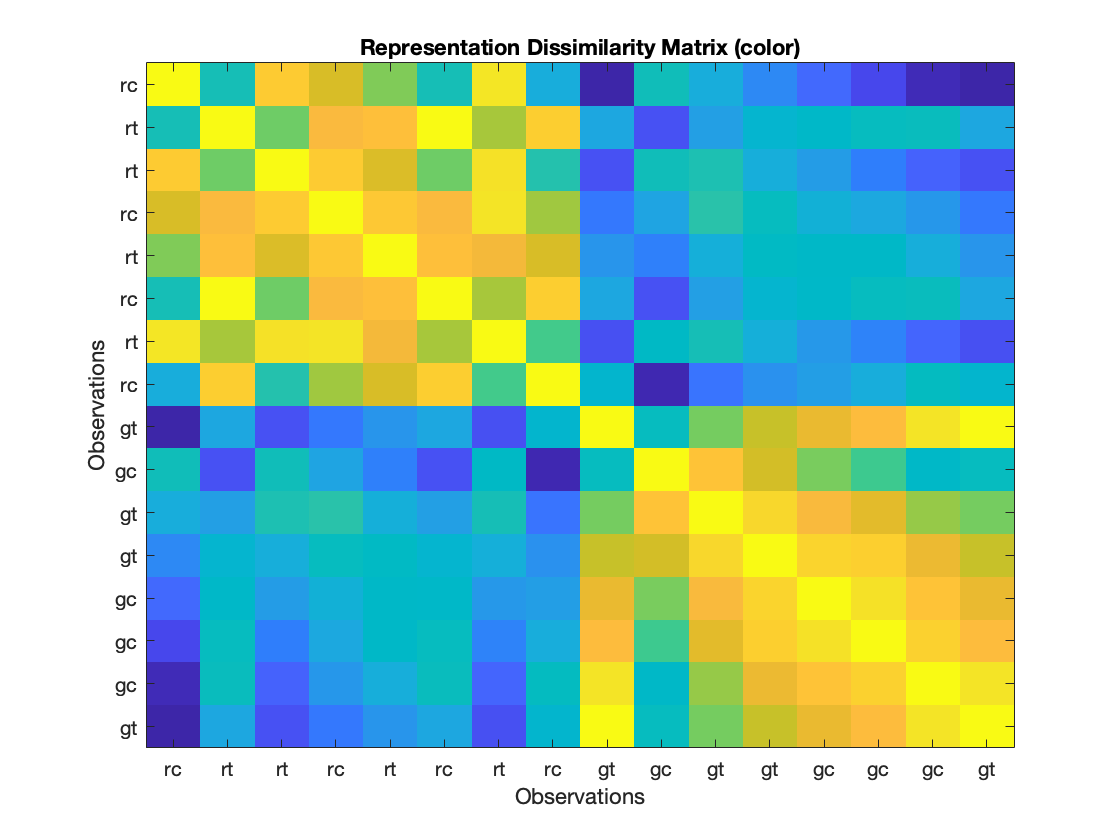

% How many observations do we have? Each beta is one observation.
n_observations = size(beta_maps,2);

% We will nest two loops to correlate each beta with every other beta
for outer_loop = 1:n_observations
    
    for inner_loop = 1:n_observations
        
        % Store correlation values in a big matrix (RDM)
        RDM_color(outer_loop, inner_loop) = corr2(sorted_betas(outer_loop,:), sorted_betas(inner_loop,:));
        
    end
end

% Let's visualize our RDM
figure
imagesc(RDM_color);xticks(1:16);yticks(1:16);xticklabels(beta_labels(ind));yticklabels(beta_labels(ind))
xlabel('Observations');ylabel('Observations');title('Representation Dissimilarity Matrix (color)')

Do you see any evident pattern now? Compare the two RDMs, what does this comparison tell you?

### Quantifying similarity

You have probably seen that the color RDM shows a more clustered pattern than the shape RDM. Of course, we can also quantify the presence of that pattern by measuring the average similarity within each condition and compare it with the mean similartiy between conditions.


% Red-red pairs and green-green pairs
within_red = mean(mean(RDM_color(1:8,1:8)))

within_red = 0.8211

within_green = mean(mean(RDM_color(9:16,9:16)))

within_green = 0.8330


% Red-green pairs and green-red pairs
between_redgreen = mean(mean(RDM_color(1:8,9:16)))

between_redgreen = 0.4367

between_greenred = mean(mean(RDM_color(9:16,1:8)))

between_greenred = 0.4367

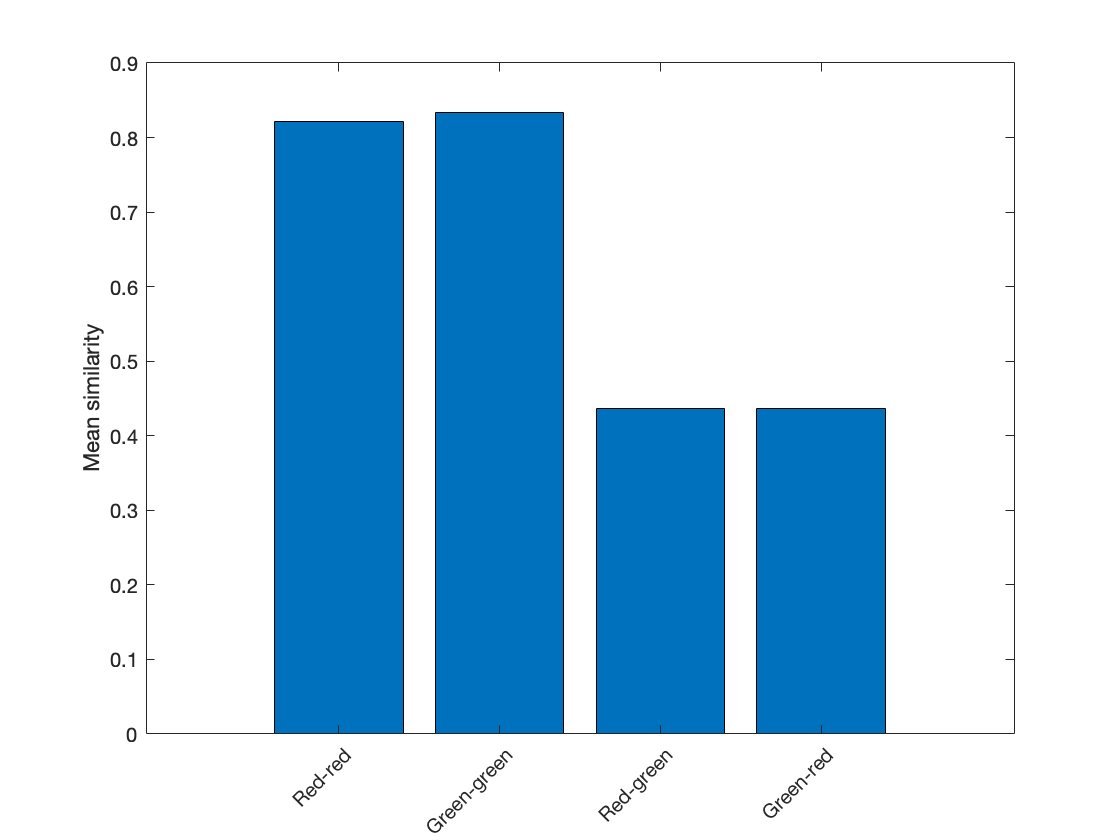


% Now we can visualize these similarity measures.
bar([within_red, within_green, between_greenred, between_redgreen])
ylabel('Mean similarity');
xticklabels({'Red-red';'Green-green'; 'Red-green'; 'Green-red'});xtickangle(45)

Since we are interested in the presence of **color** **information** in general and not specifically in red or green, we can also average across colors to get a measure of similarity for **same-color pairs** and** different-color pairs**. 

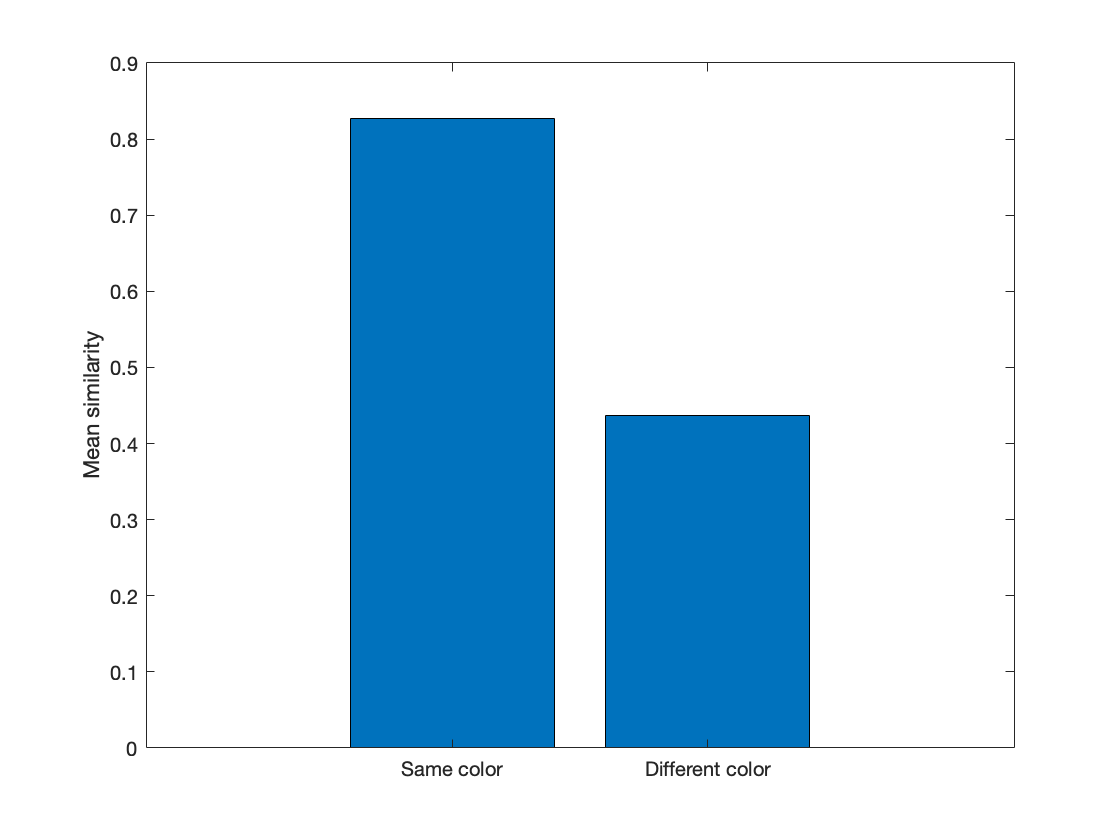

% Compute same and different color average dissimilarity
same_color = mean([within_green, within_red]);
diff_color = mean([between_redgreen, between_greenred]);

% Plot it
bar([same_color, diff_color]);
ylabel('Mean similarity');
xticklabels({'Same color';'Different color'})

If everything has worked well so far, similarity for same color pairs, should be higher than for different color pairs. What does this result mean? Can you link it to the visualization of the RDM?

### A few questions to think / discuss:

- Did you notice some redundancy in the RDM? Hint: look at the red-green and green-red similarities.

- Can you think of a way to statistically test for differences in similarity?

- If we would have used *dissimilarity* instead of similarity, what would the plot on the right look like?